# Spike Time Analysis 

Spiking actvitiy of neurons is the main focus of the [Steinmetz et al, 2019 paper](https://www.nature.com/articles/s41586-019-1787-x). In this livescript we will be visualising spikes from individual trials and cells

**Load software for working with NetCDF files**

easync_location = fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "src/easyNC");
if ~exist(easync_location)
    gitclone("https://github.com/ibehave-ibots/easyNC", easync_location)
end
addpath(easync_location)

## Download and extract data

addpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "src"))
download_from_sciebo("https://uni-bonn.sciebo.de/s/9QmOorFt6fTz4F0", "data/steinmetz_2017-01-08_Muller.nc")

Done!

addpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "data"))

ff = easyNC.Reader("data/steinmetz_2017-01-08_Muller.nc");
spike_data = ff.read2table(["spike_id","spike_trial","spike_time", "spike_cell"]);


## Visualize Spiking Activity with Scatter plots

The spiking activity is stored as a table. 

In this section we will select data from this table and visualise the spiking behaviour of single cells.

**Example Exercise**

Create a scatter plot to visualize spikes for a single neuron across multiple trials.

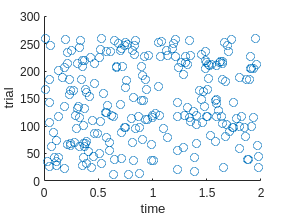

dd = spike_data(spike_data.spike_cell==12,:);
scatter(dd.spike_time, dd.spike_trial)
xlabel('time')
ylabel('trial')

**Exercises**

Create a scatter plot to visualize spikes for a neuron number 45 across multiple trials.

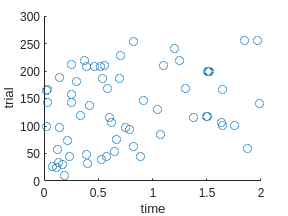

dd = spike_data(spike_data.spike_cell==45,:);
scatter(dd.spike_time, dd.spike_trial)
xlabel('time')
ylabel('trial')

Create a scatter plot to visualize spikes for a neuron number 15 across multiple trials.

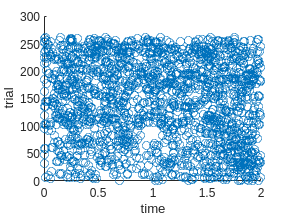

dd = spike_data(spike_data.spike_cell==15,:);
scatter(dd.spike_time, dd.spike_trial)
xlabel('time')
ylabel('trial')

Create a scatter plot to visualize spikes for a neuron number 11 across multiple trials.

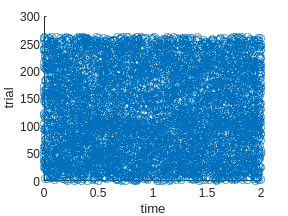

dd = spike_data(spike_data.spike_cell==11,:);
scatter(dd.spike_time, dd.spike_trial)
xlabel('time')
ylabel('trial')

Wow, that plot looks crowded! Instead of a circle,  remake the scatter plot with a horizontal bar : `|`

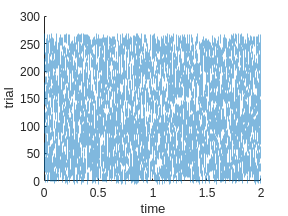

dd = spike_data(spike_data.spike_cell==11,:);
scatter(dd.spike_time, dd.spike_trial, "|")
xlabel('time')
ylabel('trial')

Create a scatter plot to visualize spikes for all neurons in trial 83.

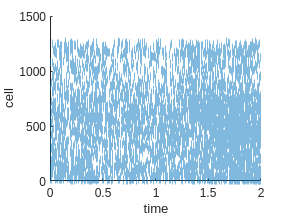

dd = spike_data(spike_data.spike_trial==83,:);
scatter(dd.spike_time, dd.spike_cell, "|")
xlabel('time')
ylabel('cell')

Remake the plot above, giving the plot an appropriate title

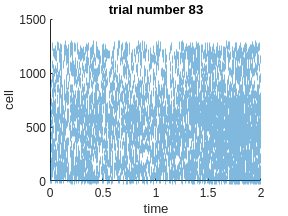

dd = spike_data(spike_data.spike_trial==83,:);
scatter(dd.spike_time, dd.spike_cell, "|")
xlabel('time')
ylabel('cell')
title('trial number 83')

## **Counting Spikes Across Trials **

The experiment is trial-based, such that we can extract meaningful results by analysing the data across all trials. 

In this section we will use table operations to learn about the number of neurons spiking across trials.

**Example Exercise**

How many spikes occurred during trial 1?

spike_cells_selected_trial = spike_data(spike_data.spike_trial==1,'spike_cell');
height(spike_cells_selected_trial)

ans = 9515

**Exercises**

How many spikes occurred during trial 24?

spike_cells_selected_trial = spike_data(spike_data.spike_trial==24,'spike_cell');
height(spike_cells_selected_trial)

ans = 7467

How many individual cells spiked during trial 24?

height(unique(spike_cells_selected_trial))

ans = 830

How many individual cells spiked during trial 108?

spike_cells_selected_trial = spike_data(spike_data.spike_trial==108,'spike_cell');
height(unique(spike_cells_selected_trial))

ans = 881

How many cells spiked during the last trial?

last_trial = spike_data.spike_trial(height(spike_data));
spike_cells_selected_trial = spike_data(spike_data.spike_trial==last_trial,'spike_cell');
height(unique(spike_cells_selected_trial))

ans = 919

Let's get the number of spiking cells per trial for all trials. To do this, we must group by the trial number and count the unique values of `spike_cell`

The code below uses `groupsummary` to calculate the number of spiking cells across tall trials.

n_spiking_cells = groupsummary(spike_data, "spike_trial","numunique", "spike_cell");


Use `n_spiking_cells` to fine the maximum number of spiking cells

max(n_spiking_cells.numunique_spike_cell)

ans = 1001

What is the minimum number of spiking cells?

min(n_spiking_cells.numunique_spike_cell)

ans = 758

Let's visualize the distribution of the number of spiking cells with a histogram.

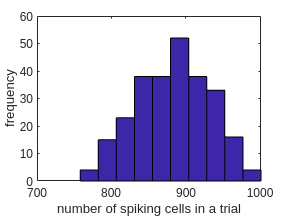

hist(n_spiking_cells.numunique_spike_cell)
xlabel('number of spiking cells in a trial')
ylabel('frequency')

## Relating spike timing to event-based variables

In this section, we will expand on the previous section and analyse spike time events jointly with other experimental events such as the `response_time.`

We will combine separate datasets into one table, while sorting and filtering the results.

**Load in data**

event_data = ff.read2table(["trial","response_time",  "gocue", "active_trials"]);

**Example Exercise**

Make a scatterplot of response time vs. trial number 

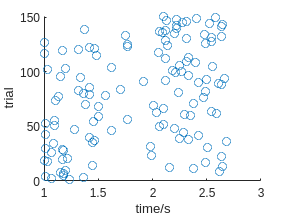

scatter(event_data.response_time, event_data.trial)
xlabel('time/s')
ylabel('trial')

Make a scatterplot of gocue time vs. trial number

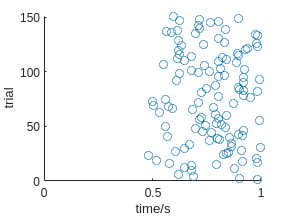

scatter(event_data.gocue, event_data.trial)
xlabel('time/s')
ylabel('trial')

Sort the rows of `data_events` by response time and name the result `data_events_sorted`

data_events_sorted = sortrows(event_data, "response_time");

Make a scatterplot of sorted response time vs.  the rank of the sorted response times

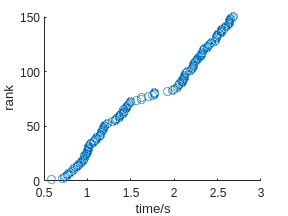

scatter(data_events_sorted.response_time, [1:height(data_events_sorted)])
xlabel('time/s')
ylabel('rank')

We want to add spiking events to the above plot. To do so however, we will need to sort the spiking events according to the response times. 

The first step is to combine the spiking and response data via a join. A join combines two tables by joining them along defined columns.

Fill in the blanks in the code below to perform the join

%data = join(spike_data, data_events, "LeftKeys","___", "RightKeys","___");
data = join(spike_data, event_data, "LeftKeys","spike_trial", "RightKeys","trial");


Find the rows of spike_data where the cell number is 48 and the trial is active ( ie. 1). Name the result `cell_48_active`

cell_48_active = data(data.spike_cell==48 & data.active_trials==1,:);

Sort the rows of cell_48_active by the response time. Name the result `cell_48_active_sorted`

cell_48_active_sorted = sortrows(cell_48_active , "response_time");

The code below makes a scatter plot showing both the sorted response times and the sorted spike times vs. the response time rank. Fill in the blanks with the appropriate variables

This is known as a rasterplot

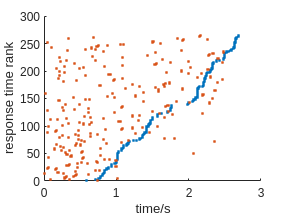

clf
hold on
scatter(cell_48_active_sorted.response_time, [1:height(cell_48_active_sorted)],'.')
scatter(cell_48_active_sorted.spike_time, [1:height(cell_48_active_sorted)],'.')
hold off
xlabel('time/s')
ylabel('response time rank')

Make a similar rasterplot but for cell 187

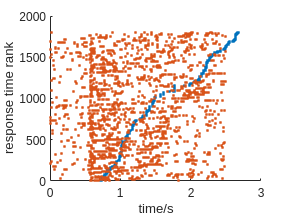

dd= data(data.spike_cell==187 & data.active_trials==1,:);
dd_sorted = sortrows(dd, "response_time");
clf
hold on
scatter(dd_sorted.response_time, [1:height(dd_sorted)],'.')
scatter(dd_sorted.spike_time, [1:height(dd_sorted)],'.')
hold off
xlabel('time/s')
ylabel('response time rank')

Why does neuron spiking activity increase dramatically after 0.5s for this cell? **Hint**- consider the distribution of timing events